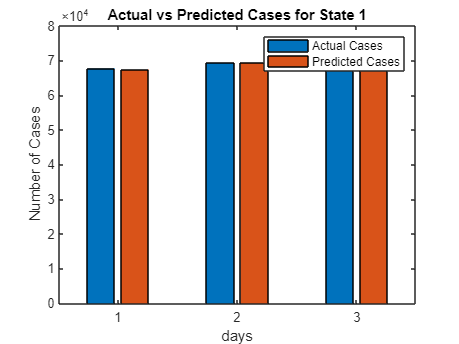

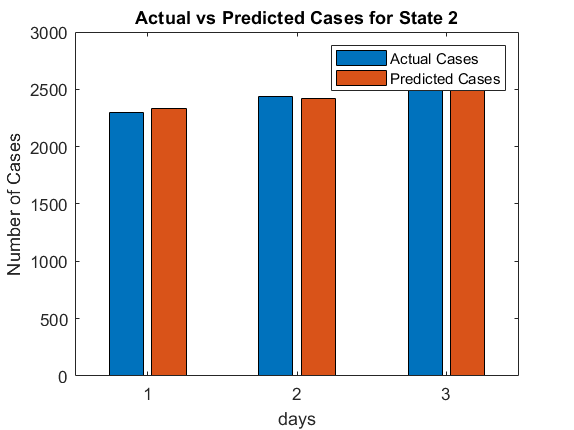

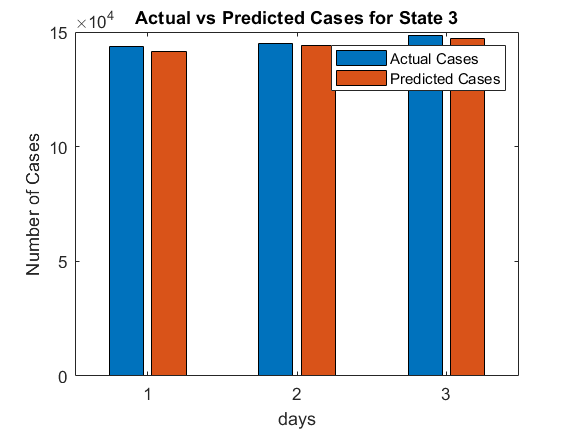

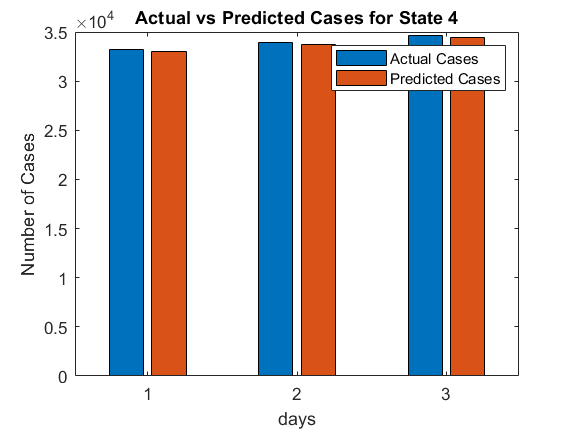

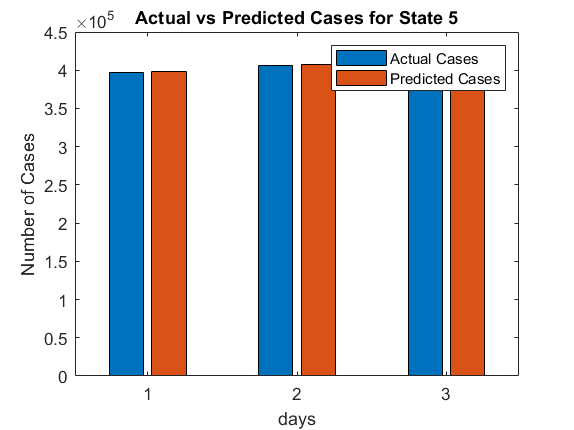

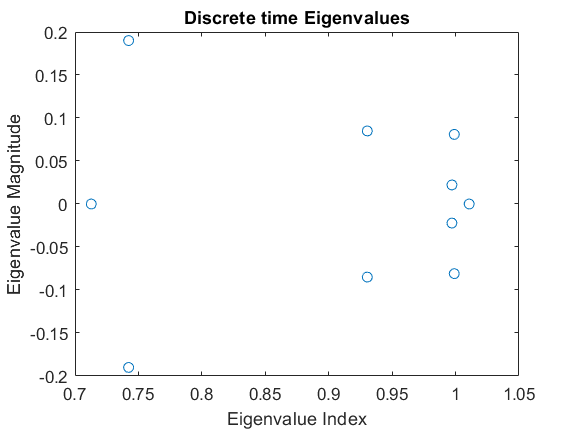

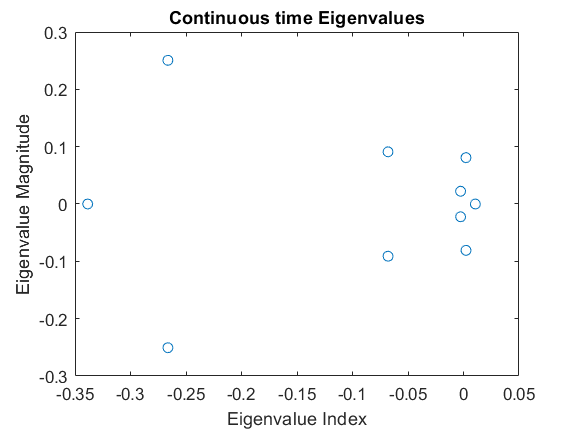

RMSE of the predicted value is: 7.460153e+02


MSE of the predicted value is: 5.565388e+05


MAE of the predicted value is: 3.416969e+02


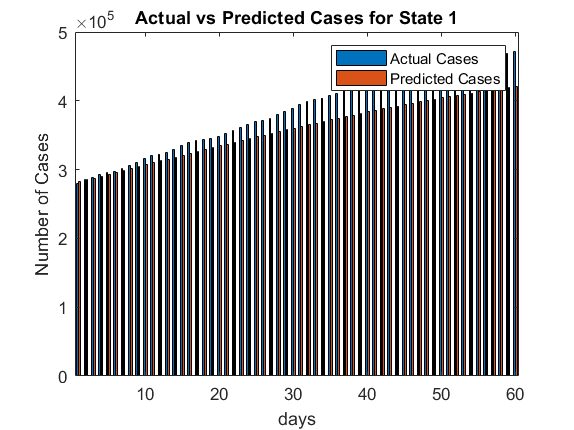

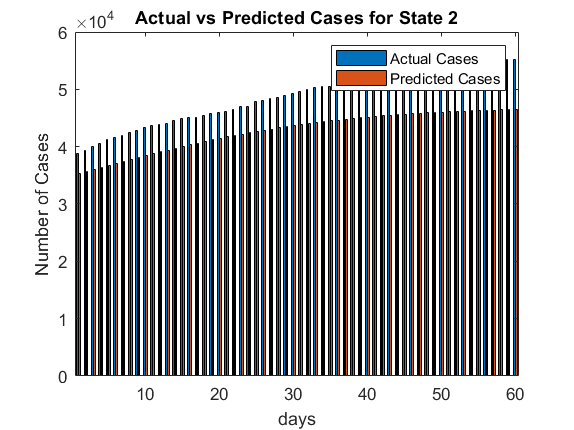

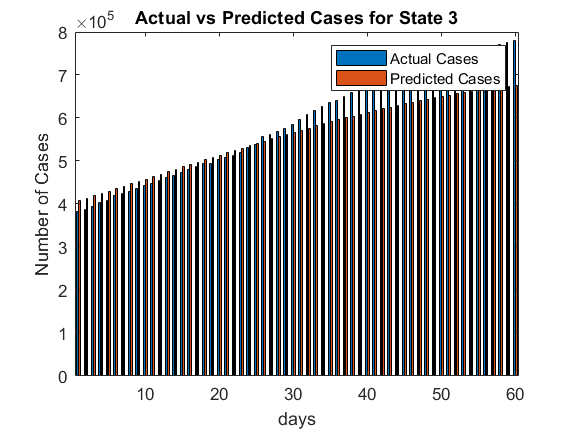

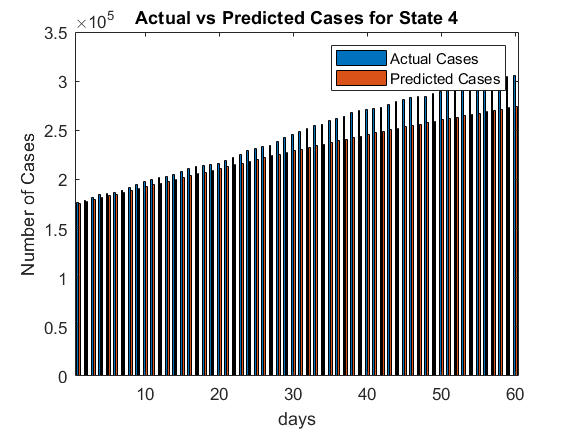

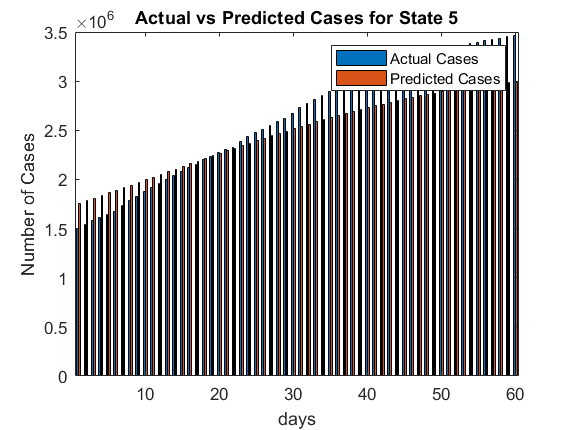

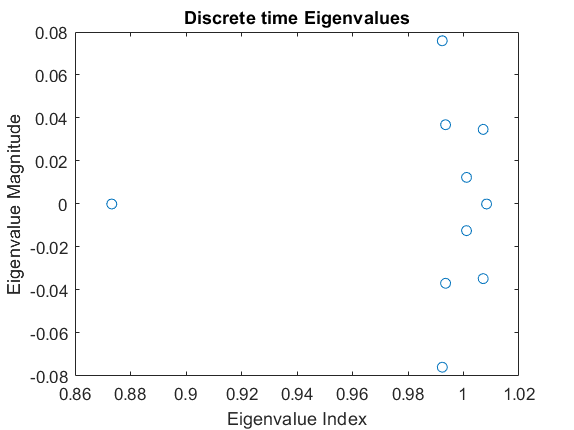

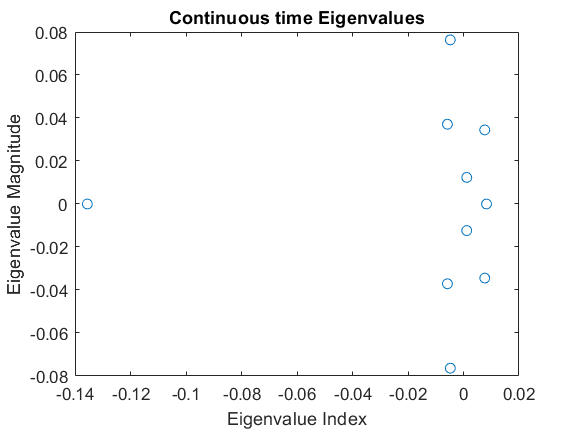

RMSE of the predicted value is: 6.033428e+04


MSE of the predicted value is: 3.640226e+09


MAE of the predicted value is: 3.287776e+04


State 46 - RMSE: 28.8992, MSE: 835.1634, MAE: 27.1799


State 50 - RMSE: 4.933, MSE: 24.3344, MAE: 4.1586


State 7 - RMSE: 262.0013, MSE: 68644.6955, MAE: 257.3651


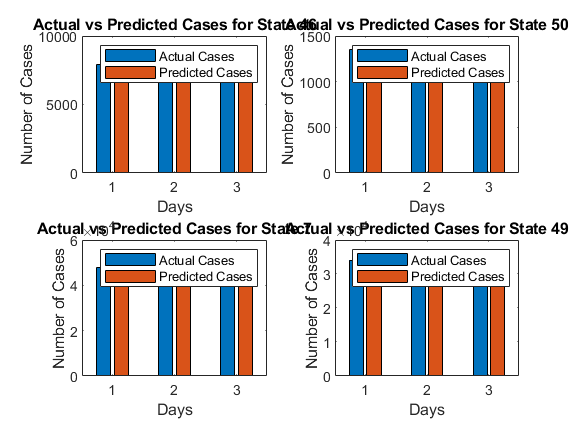

State 49 - RMSE: 355.1534, MSE: 126133.9195, MAE: 314.8109


State 36 - RMSE: 572.4941, MSE: 327749.5091, MAE: 494.8482


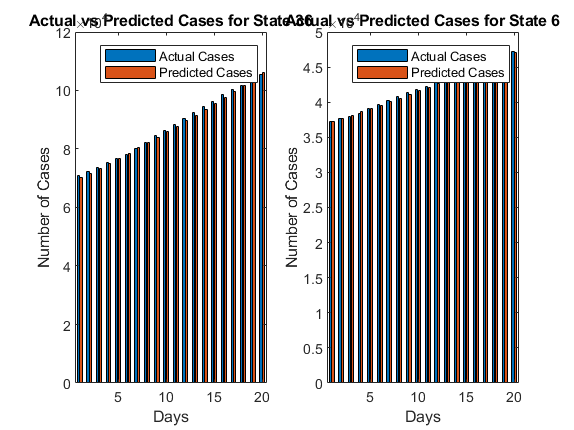

State 6 - RMSE: 190.5874, MSE: 36323.5499, MAE: 163.5606


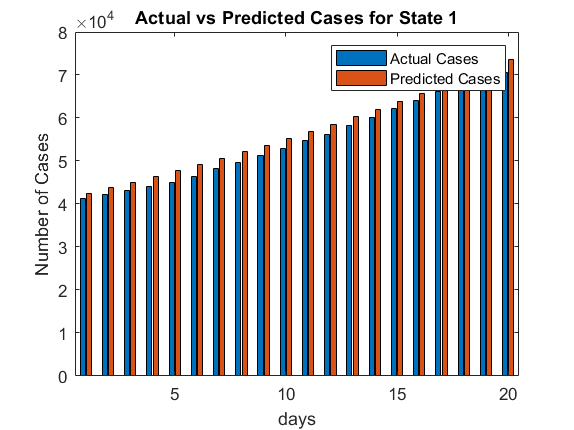

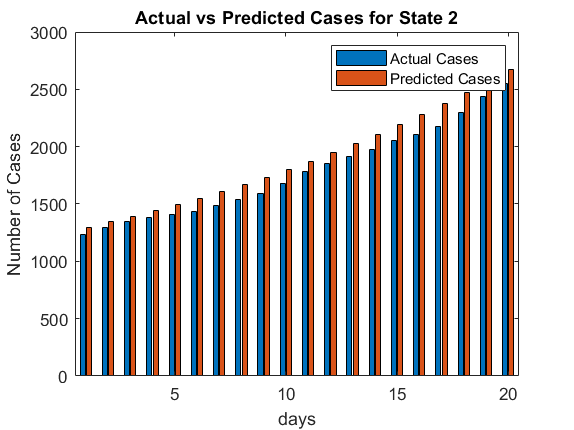

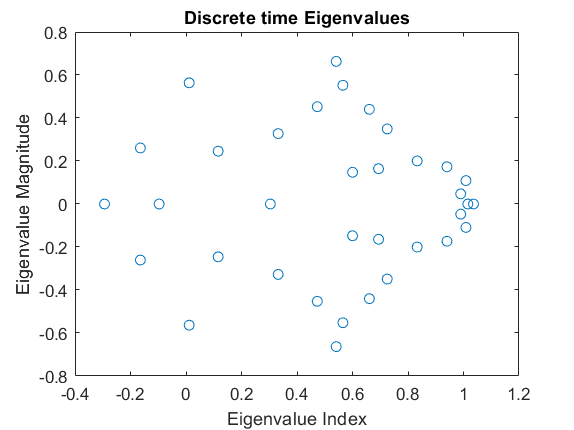

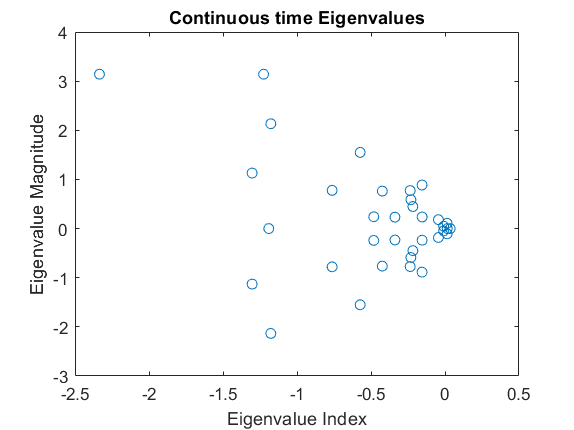

RMSE of the predicted value is: 4.522746e+03


MSE of the predicted value is: 2.045523e+07


MAE of the predicted value is: 2.015070e+03


State 29 - RMSE: 28.7233, MSE: 825.0253, MAE: 23.0646


State 37 - RMSE: 24.3388, MSE: 592.3776, MAE: 20.7044


State 43 - RMSE: 81.0411, MSE: 6567.6541, MAE: 66.1114


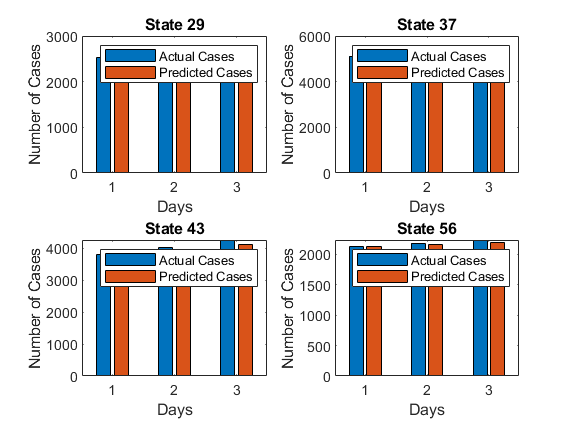

State 56 - RMSE: 25.9357, MSE: 672.6619, MAE: 21.454


State 55 - RMSE: 128.9723, MSE: 16633.8587, MAE: 87.5974


State 56 - RMSE: 25.9357, MSE: 672.6619, MAE: 21.454


errper2 = 	1.0e+12 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    

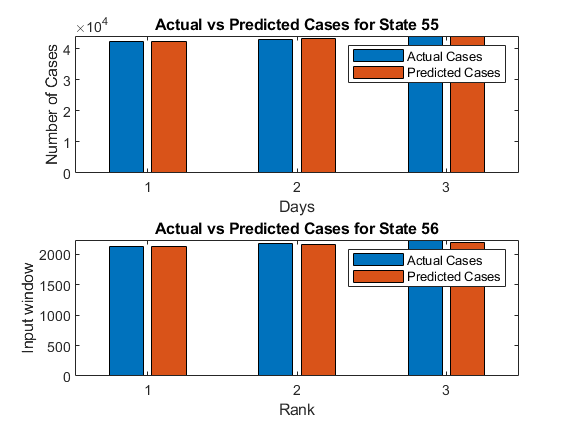

We have minimum error percentage 0.000563 at Rank 22 with input window of 70 days

clc;
clear all;
close all;
data1 = readtable('C:\Users\GAYATHRI DEVI R V\Downloads\dataset_cov.csv');
data = table2array(data1(2:end, 4:end));

c0 = input("Enter 1 to perform analysis of DMD or Enter 2 to use interactive prediction of cases: ");
if c0 == 1
    % Case 1: Rank 10, Number of columns to be taken for X: 100, Prediction: 3
    r = 10; % truncating rank test window
    start = 80; % starting point of X matrix
    maximum = 100; % number of columns in X matrix
    predict = 3; % number of values to predict
    dt = 1; % time
    n = 5; % number of observations to plot
    
    [l, o, p] = DMD(data, start, maximum, predict, r, 1, 0); % calling dmd function
    
    % Plot actual and predicted cases for each state as bar graphs
    for state_idx = 1:n
        figure;
        bar(1:predict, [data(state_idx, start + maximum - predict + 1:start + maximum); p(state_idx, :)]');
        title("Actual vs Predicted Cases for State " + state_idx);
        xlabel("days");
        ylabel("Number of Cases");
        legend("Actual Cases", "Predicted Cases");
    end

    
    % Plot Discrete and Continuous time Eigenvalues
    figure;
    plot(l, 'o');
    title("Discrete time Eigenvalues");
    xlabel("Eigenvalue Index");
    ylabel("Eigenvalue Magnitude");
    
    figure;
    plot(o, 'o');
    title("Continuous time Eigenvalues");
    xlabel("Eigenvalue Index");
    ylabel("Eigenvalue Magnitude");
    
    % Calculate errors
    d1 = data(:, start + maximum - predict + 1:start + maximum);
    d2 = p(:, :);
    rmse_err = rmse(d1, d2); % Root mean square error
    mse_err = mse(data(:, start + maximum - predict + 1:start + maximum), p(:, :));
    mae_err = mae(d1, d2);
    disp("RMSE of the predicted value is: " + sprintf('%e', rmse_err));
    disp("MSE of the predicted value is: " + sprintf('%e', mse_err));
    disp("MAE of the predicted value is: " + sprintf('%e', mae_err));
    
    % Case 2: Rank 10, Number of columns to be taken for X: 300, Prediction: 60
    r = 10; % truncating rank test window
    start = 80; % starting point of X matrix
    maximum = 300; % number of columns in X matrix
    predict = 60; % number of values to predict
    
    [l, o, p] = DMD(data, start, maximum, predict, r, 1, 0); % calling dmd function
    
    for state_idx = 1:n
        figure;
        bar(1:predict, [data(state_idx, start + maximum - predict + 1:start + maximum); p(state_idx, :)]');
        title("Actual vs Predicted Cases for State " + state_idx);
        xlabel("days");
        ylabel("Number of Cases");
        legend("Actual Cases", "Predicted Cases");
    end
    
    % Plot Discrete and Continuous time Eigenvalues
    figure;
    plot(l, 'o');
    title("Discrete time Eigenvalues");
    xlabel("Eigenvalue Index");
    ylabel("Eigenvalue Magnitude");
    
    figure;
    plot(o, 'o');
    title("Continuous time Eigenvalues");
    xlabel("Eigenvalue Index");
    ylabel("Eigenvalue Magnitude");
    
    % Calculate errors
    d1 = data(:, start + maximum - predict + 1:start + maximum);
    d2 = p(:, :);
    rmse_err = rmse(d1, d2); % Root mean square error
    mse_err = mse(data(:, start + maximum - predict + 1:start + maximum), p(:, :));
    mae_err = mae(d1, d2);
    disp("RMSE of the predicted value is: " + sprintf('%e', rmse_err));
    disp("MSE of the predicted value is: " + sprintf('%e', mse_err));
    disp("MAE of the predicted value is: " + sprintf('%e', mae_err));

    % Case: Rank 10, Start 80, Maximum 100, Predict 3, States 4
    r = 10;       % Truncating rank test window
    start = 80;   % Starting point of X matrix
    maximum = 100; % Number of columns in X matrix
    predict = 3;   % Number of values to predict
    n = 4;         % Number of states to plot
    
    [l, o, p] = DMD(data, start, maximum, predict, r, 1, 0); % Calling DMD function
    
    % Plot actual and predicted cases for random 4 states
    states_to_plot = randperm(size(data, 1), n); % Randomly select 4 states

    %Create a 2x2 grid of subplots for the bar graphs
    figure;
    error_values = zeros(n, 3); % RMSE, MSE, MAE for all 4 states
    
    for i = 1:n
        state_idx = states_to_plot(i);
        subplot(2, 2, i);
        bar(1:predict, [data(state_idx, start + maximum - predict + 1:start + maximum); p(state_idx, :)]');
        title("Actual vs Predicted Cases for State " + state_idx);
        xlabel("Days");
        ylabel("Number of Cases");
        legend("Actual Cases", "Predicted Cases");

         % Calculate errors
         d1 = data(state_idx, start + maximum - predict + 1:start + maximum);
         d2 = p(state_idx, :);
         rmse_err = rmse(d1, d2); % Root mean square error
         mse_err = mse(d1, d2);
         mae_err = mae(d1, d2);
         
         error_values(i, 1) = rmse_err;
         error_values(i, 2) = mse_err;
         error_values(i, 3) = mae_err;
         
         disp("State " + state_idx + " - RMSE: " + rmse_err + ", MSE: " + mse_err + ", MAE: " + mae_err);
    end

    % Case: Rank 10, Start 80, Maximum 100, Predict 20, States 2
    r = 10;       % Truncating rank test window
    start = 80;   % Starting point of X matrix
    maximum = 100; % Number of columns in X matrix
    predict = 20;   % Number of values to predict
    n = 2;         % Number of states to plot
    
    [l, o, p] = DMD(data, start, maximum, predict, r, 1, 0); % Calling DMD function
    
    % Plot actual and predicted cases for random 2 states
    states_to_plot = randperm(size(data, 1), n); % Randomly select 2 states

    %Create a 2x2 grid of subplots for the bar graphs
    figure;
    error_values = zeros(n, 3); % RMSE, MSE, MAE for all 4 states
    
    for i = 1:n
        state_idx = states_to_plot(i);
        subplot(1, 2, i);
        bar(1:predict, [data(state_idx, start + maximum - predict + 1:start + maximum); p(state_idx, :)]');
        title("Actual vs Predicted Cases for State " + state_idx);
        xlabel("Days");
        ylabel("Number of Cases");
        legend("Actual Cases", "Predicted Cases");

         % Calculate errors
         d1 = data(state_idx, start + maximum - predict + 1:start + maximum);
         d2 = p(state_idx, :);
         rmse_err = rmse(d1, d2); % Root mean square error
         mse_err = mse(d1, d2);
         mae_err = mae(d1, d2);
         
         error_values(i, 1) = rmse_err;
         error_values(i, 2) = mse_err;
         error_values(i, 3) = mae_err;
         
         disp("State " + state_idx + " - RMSE: " + rmse_err + ", MSE: " + mse_err + ", MAE: " + mae_err);
    end
    
    % Case 3: Rank 35, Number of columns to be taken for X: 100, Prediction: 20
    r =  35; % truncating rank test window
    start = 80; % starting point of X matrix
    maximum = 100; % number of columns in X matrix
    predict = 20; % number of values to predict
    
    [l, o, p] = DMD(data, start, maximum, predict, r, 1, 0); % calling dmd function
    
    % Plot actual and predicted cases for each state
    for state_idx = 1:n
        figure;
        bar(1:predict, [data(state_idx, start + maximum - predict + 1:start + maximum); p(state_idx, :)]');
        title("Actual vs Predicted Cases for State " + state_idx);
        xlabel("days");
        ylabel("Number of Cases");
        legend("Actual Cases", "Predicted Cases");
    end
    
    % Plot Discrete and Continuous time Eigenvalues
    figure;
    plot(l, 'o');
    title("Discrete time Eigenvalues");
    xlabel("Eigenvalue Index");
    ylabel("Eigenvalue Magnitude");
    
    figure;
    plot(o, 'o');
    title("Continuous time Eigenvalues");
    xlabel("Eigenvalue Index");
    ylabel("Eigenvalue Magnitude");
    
    % Calculate errors
    d1 = data(:, start + maximum - predict + 1:start + maximum);
    d2 = p(:, :);
    rmse_err = rmse(d1, d2); % Root mean square error
    mse_err = mse(data(:, start + maximum - predict + 1:start + maximum), p(:, :));
    mae_err = mae(d1, d2);
    disp("RMSE of the predicted value is: " + sprintf('%e', rmse_err));
    disp("MSE of the predicted value is: " + sprintf('%e', mse_err));
    disp("MAE of the predicted value is: " + sprintf('%e', mae_err));

    %new
    % Case: Rank 10, Start 80, Maximum 100, Predict 3, States 4
    r = 10;       % Truncating rank test window
    start = 80;   % Starting point of X matrix
    maximum = 100; % Number of columns in X matrix
    predict = 3;   % Number of values to predict
    n = 4;         % Number of states to plot
    
    [l, o, p] = DMD(data, start, maximum, predict, r, 1, 0); % Calling DMD function
    
    % Specify the states for which you want to find RMSE, MSE, MAE
    specified_states = [29,37,43,56]; % Replace this with the states you want
    
    % Create a grid of subplots for the bar graphs
    num_specified_states = length(specified_states);
    rows = ceil(sqrt(num_specified_states));
    cols = ceil(num_specified_states / rows);
    
    figure;
    error_values = zeros(num_specified_states, 3); % RMSE, MSE, MAE for specified states
    
    for i = 1:num_specified_states
        state_idx = specified_states(i);
        subplot(rows, cols, i);
        bar(1:predict, [data(state_idx, start + maximum - predict + 1:start + maximum); p(state_idx, :)]');
        title("State " + state_idx);
        xlabel("Days");
        ylabel("Number of Cases");
        legend("Actual Cases", "Predicted Cases");

        % Calculate errors
        d1 = data(state_idx, start + maximum - predict + 1:start + maximum);
        d2 = p(state_idx, :);
        rmse_err = rmse(d1, d2); % Root mean square error
        mse_err = mse(d1, d2);
        mae_err = mae(d1, d2);
        
        error_values(i, 1) = rmse_err;
        error_values(i, 2) = mse_err;
        error_values(i, 3) = mae_err;
        
        disp("State " + state_idx + " - RMSE: " + rmse_err + ", MSE: " + mse_err + ", MAE: " + mae_err);
    end

    %new_to_delete
    % Case: Rank 10, Start 80, Maximum 100, Predict 3, States 4
    r = 10;       % Truncating rank test window
    start = 80;   % Starting point of X matrix
    maximum = 100; % Number of columns in X matrix
    predict = 3;   % Number of values to predict
    n = 2;         % Number of states to plot
    
    [l, o, p] = DMD(data, start, maximum, predict, r, 1, 0); % Calling DMD function
    
    % Specify the states for which you want to find RMSE, MSE, MAE
    specified_states = [55,56]; % Replace this with the states you want
    
    % Create a grid of subplots for the bar graphs
    num_specified_states = length(specified_states);
    rows = ceil(sqrt(num_specified_states));
    cols = ceil(num_specified_states / rows);
    
    figure;
    error_values = zeros(num_specified_states, 3); % RMSE, MSE, MAE for specified states
    
    for i = 1:num_specified_states
        state_idx = specified_states(i);
        subplot(rows, cols, i);
        bar(1:predict, [data(state_idx, start + maximum - predict + 1:start + maximum); p(state_idx, :)]');
        title("Actual vs Predicted Cases for State " + state_idx);
        xlabel("Days");
        ylabel("Number of Cases");
        legend("Actual Cases", "Predicted Cases");

        % Calculate errors
        d1 = data(state_idx, start + maximum - predict + 1:start + maximum);
        d2 = p(state_idx, :);
        rmse_err = rmse(d1, d2); % Root mean square error
        mse_err = mse(d1, d2);
        mae_err = mae(d1, d2);
        
        error_values(i, 1) = rmse_err;
        error_values(i, 2) = mse_err;
        error_values(i, 3) = mae_err;
        
        disp("State " + state_idx + " - RMSE: " + rmse_err + ", MSE: " + mse_err + ", MAE: " + mae_err);
    end


    errper2=[];
    for a=1:size(data,1)
        errper1=[];
        for b=40:20:500
            r=a; %truncating rank test window
            start=80; %starting point of X matrix
            maximum=b; %number of columns in X matrix
            predict=10; %number of values to predict
            dt=1; %time
            n=10; %number of observation to plot
            
            [l,o,p]=DMD(data,start,maximum,predict,r,1,0); %calling dmd function
            
            d1=data(:,start+maximum-predict+1:start+maximum);
            d2=p(:,:);
            c=max(max(data(:,start+maximum-predict+1:start+maximum)));
            err=rmse(d1,d2); %Root mean square error
            errper=err/c; %Erroe percentage(Assuming error will be less than maximum value)
            
            errper1=[errper1 errper];
        end
        errper2=[errper2;errper1];
    end
    errper2
    
    %surf(errper2) %plotting eerror percentage
    xlabel('Rank');
    ylabel('Input window');
    zlabel('Error Percentage');
    
    minimum = min(min(errper2)); 
    [x,y]=find(errper2==minimum);
    fprintf("We have minimum error percentage %f at Rank %d with input window of %d days",minimum,x,y*20+50); 
end


if c0 == 2
    % Interactive cases prediction
    c1 = input("Enter 1 if you want to predict within the input window (Easy for comparison) or Enter 2 if you want to predict the cases in the future: ");
    c3 = input("Enter the number of States you want to see in observation (Recommended is 20 or less for clear observation): ");
    
    r = 10; % truncating rank test window
    start = 80; % starting point of X matrix
    maximum = 100; % number of columns in X matrix
    predict = 80;
    dt = 1; % time
    n = c3; % number of observations to plot
    
    if c1 == 1
        n1 = 0;
    elseif c1 == 2
        c2 = input("Enter The number of days you want to predict: ");
        n1 = c2;
    else
        disp("Enter a valid option: ");
    end
    
    [l, o, p] = DMD(data, start, maximum, predict, r, 1, n1); % calling dmd function
    
    if c1 == 1
        d1 = data(:, start + maximum - predict + 1:start + maximum);
        d2 = p(:, :);
        
        % Calculate RMSE
        err = rmse(d1, d2); % Root mean square error
        disp("RMSE of the predicted value is: " + err);
        
        % Plot actual and predicted cases for each state
        for state_idx = 1:n
            figure;
            bar(1:predict, [data(state_idx, start + maximum - predict + 1:start + maximum); p(state_idx, :)]');
            title("Actual vs Predicted Cases for State " + state_idx);
            xlabel("days");
            ylabel("Number of Cases");
            legend("Actual Cases", "Predicted Cases");
        end
    else
        % Plot predicted cases for each state
        %for state_idx = 1:n
        %    figure;
        %    plot(1:n1, p(state_idx, :), 'r--', 'DisplayName', 'Predicted Cases');
        %    title("Predicted Cases for State " + state_idx);
        %    xlabel("days");
        %    ylabel("Number of Cases");
        %    legend;
        %end
        
        % Plot predicted cases for each state as a scatter plot
        % Plot predicted cases for each state as a scatter plot with whole number values
        for state_idx = 1:n
            figure;
            predicted_values = p(state_idx, :); % Extract real parts
            scatter(1:n1, predicted_values, 'r', 'filled', 'DisplayName', 'Predicted Cases');
            title("Predicted Cases for State " + state_idx);
            xlabel("days");
            ylabel("Number of Cases");
            % Add text labels for each point as whole numbers
            for i = 1:n1
                text(i, predicted_values(i), num2str(round(predicted_values(i)), '%d'), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
            end
            legend;
        end




    end
    
    % Plot Discrete and Continuous time Eigenvalues
    figure;
    plot(l, 'o');
    title("Discrete time Eigenvalues");
    xlabel("Eigenvalue Index");
    ylabel("Eigenvalue Magnitude");
    
    figure;
    plot(o, 'o');
    title("Continuous time Eigenvalues");
    xlabel("Eigenvalue Index");
    ylabel("Eigenvalue Magnitude");
end


function [lambda, omega, pred] = DMD(Xaug, start, m, l, r, dt, n1)
    X = Xaug(:, start:start + m);
    Y = Xaug(:, start + 1:start + m + 1);
    
    % SVD and truncate to first r modes
    [U, S, V] = svd(X, "econ");
    
    r = min(r, size(U, 2));
    
    U_r = U(:, 1:r); % truncate to rank-r
    S_r = S(1:r, 1:r);
    V_r = V(:, 1:r);
    
    Atilde = U_r' * Y * V_r / S_r; % Low-rank dynamics
    
    [W_r, D] = eig(Atilde);
    
    Phi = Y * V_r / S_r * W_r; % DMD modes
    lambda = diag(D); % discrete-time eigenvalues
    omega = log(lambda) / dt; % continuous-time eigenvalues
    
    x1 = X(:, 1); % X0
    b = Phi \ x1;
    
    mm1 = size(X, 2) + n1; % mm1 = m - 1
    time_dynamics = zeros(r, mm1);
    t = (0:mm1 - 1) * dt; % time vector
    
    for iter = 1:mm1
        time_dynamics(:, iter) = (b .* exp(omega * t(iter)));
    end
    
    Xdmd = Phi * time_dynamics;
    
    if n1 == 0
        pred = Xdmd(:, end - l + 1:end);
    else
        pred = Xdmd(:, end - n1 + 1:end);
    end
end

function rmse = rmse(a, b)
    D = abs(a - b).^2;
    rmse = sqrt(sum(D(:)) / numel(a));
end

function mse = mse(a,b)
   D = abs(a-b).^2;
   mse = mean(D(:));
end

function mae = mae(a,b)
   D = abs(a-b);
   mae = mean(D(:));
end